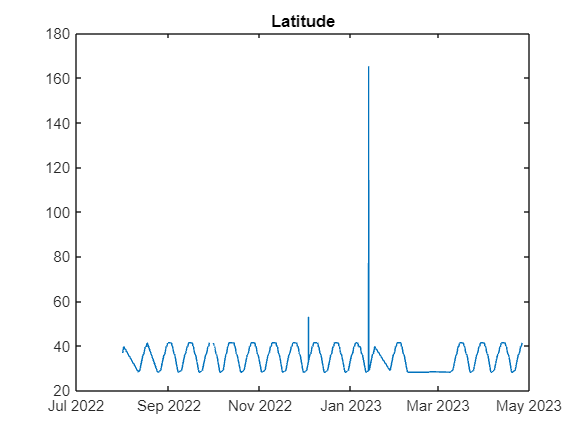

A.GPSDate.Format = "dd/MM/uuuu HH:mm:ss";
A.gpsTime.Format = "dd/MM/uuuu HH:mm:ss";

A.Date = A.GPSDate + timeofday(A.gpsTime);
A.JulianDate = exceltime(A.Date);

% Coordenadas
plot(A.Date, A.latitude)
title("Latitude")

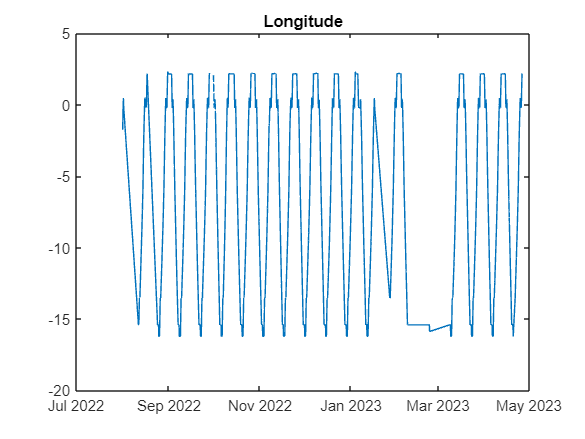


plot(A.Date, A.longitude)
title("Longitude")

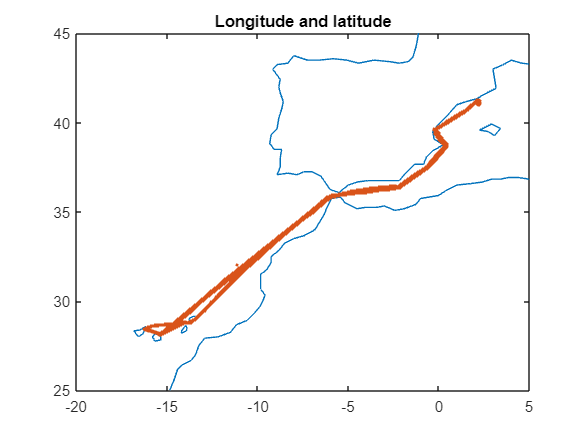


% Obtener las coordenadas máximas y mínimas medidas para comprobar si hay algún error
coord = table(min(A.longitude), min(A.latitude), max(A.longitude), max(A.latitude), 'VariableNames', {'minLon', 'minLat', 'maxLon', 'maxLat'});

load coastlines
plot(coastlon, coastlat)
hold on 
plot(A.longitude, A.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

Af = A(A.latitude < 29.20 & A.latitude > 28.50 & A.longitude < -15.4 & A.longitude > -15.6 & A.Type == "EQU", :);

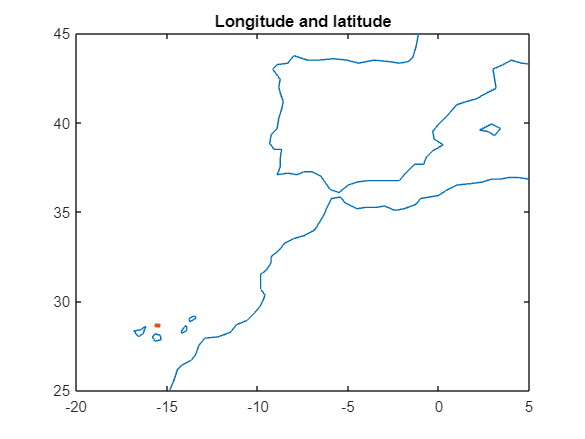

plot(coastlon, coastlat)
hold on 
plot(Af.longitude, Af.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

data = Af(:, ["Date","JulianDate","latitude","longitude","pCO2sw","fCO2sw", "IntakeTemp", "SAL"]);
writetable(data, 'nearSTOC.csv', 'Delimiter', '\t')